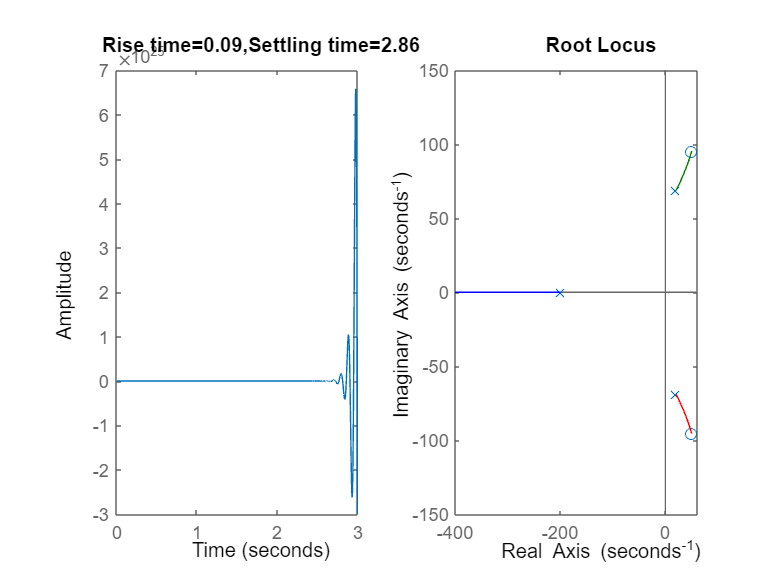

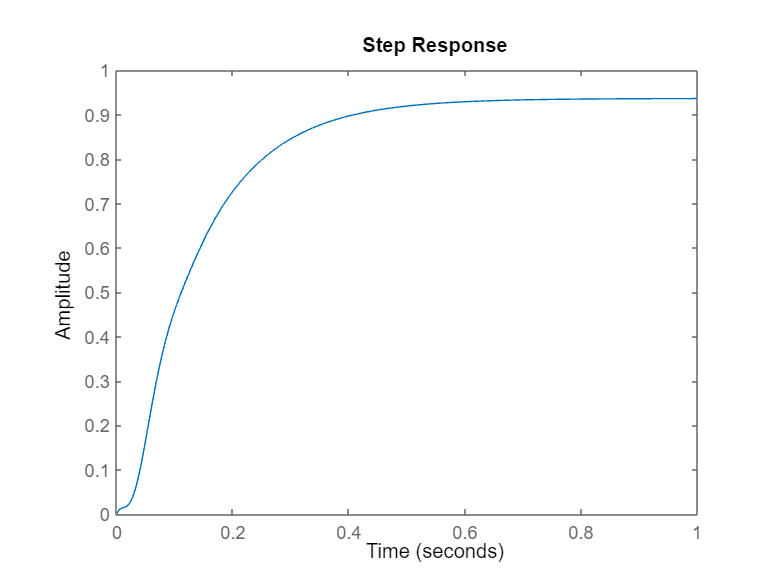

den= [0 1 74.38 5589 42107];
num= [0 0 3.392 -340.09 39451];
G=tf(num,den);
for k=input("Enter k: ")
    system=feedback(k*G,1);
    subplot(1,2,1);
    [y,t]=step(system);
    stepinfo_str= stepinfo(y,t);
    step(system);
    title(sprintf("Rise time=%.2f,Settling time=%.2f",stepinfo_str.RiseTime,stepinfo_str.SettlingTime));
    subplot(1,2,2);
    rlocus(system);
    figure;
    step(G);
    %poles=pole(system);
    %if all(real(poles)<0)
     %   disp('system is unstable');
    %else
     %           disp('system is stable');
    %end
end